# Workflow Load RRNG file into your mass Spectra

With the following workflow you can load a .rrng file into your mass Spectra. 

% Load in the pos table and create the mass spectra
pos = posToTable();
spec = massSpecPlot(pos,.01);

% Load the .rrng file, colorScheme and the isotopeTable
[file path] = uigetfile('*.rrng');
load('colorScheme.mat')
load('isotopeTable_naturalAbundances.mat')

% extract the Elements from the .rrng file and creat an ionList
elements = elementsExtractFromText(fileread([path file]));
ionList = ionsCreateComplex(elements,[1 2],isotopeTable,[1 2 3]);

%split the .rrng file into strings
rrng = string(splitlines(fileread([path file])));
rrng(rrng == "") = [];
useRrngColor = true;

Create for a range information from the .rrng file and at it to the spectrum 

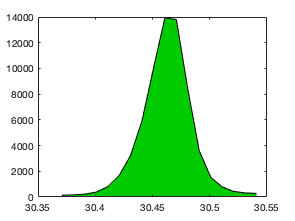

Index exceeds the number of array elements. Index must not exceed 0.

Error in matlab.internal.datatypes.parenReference_1D (line 12)
    data = data(rowIndices);

Error in categorical/parenReference (

for i=1:length(rrng)
    [mcBegin, mcEnd, ionName, ionVolume, ionColor] = rangeInfoFromRRNG(rrng(i));
    if not(isempty(mcBegin))
    [h, txt, colorScheme] = rangeAddFromRangeInfo(spec, colorScheme, isotopeTable, ionList, mcBegin, mcEnd, ionName, ionVolume, ionColor, useRrngColor);
    end
end